clf;
homedir='\Users\editabulovaite\Documents\PhD_Year2\region_puncta_distribution\Edita_punctanew\';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 2;



turnover_dir=dir('eGFP_Halo_density_Day0.csv');
turnover_dir = readtable(turnover_dir.name);


MEAN_Halo =turnover_dir(:,2);
MEAN_Halo=table2array(MEAN_Halo);
SD_Halo =turnover_dir(:,3);
SD_Halo=table2array(SD_Halo);
MEAN_eGFP =turnover_dir(:,4);
MEAN_eGFP=table2array(MEAN_eGFP);
SD_eGFP =turnover_dir(:,5);
SD_eGFP=table2array(SD_eGFP);

Regions =turnover_dir(:,6);
Regions = table2array(Regions);
Regions = categorical(Regions);

c=[0.07 0.3 0.33; 0.99 0.88 0.59; 0.92 0.32 0.59; 0.95 0.75 0.85; 0.2 0.68 0.89; 0.64 0.31 0.08; 0.9 0.35 0.48; 0.14 0.04 0.05; 0.81 0.83 0.08; 0.09 0.22 0.44; 0.08 0.31 0.15; 0.41 0.74 0.64];
eb(1) = errorbar(MEAN_eGFP,MEAN_Halo,SD_eGFP, 'vertical', 'LineStyle', 'none');
hold on
eb(2) = errorbar(MEAN_eGFP,MEAN_Halo,SD_Halo, 'horizontal', 'LineStyle', 'none');
set(eb, 'color',uisetcolor, 'LineWidth', 0.8)
hold on
gscatter(MEAN_eGFP,MEAN_Halo,Regions,c,'.',30);
legend("Location","bestoutside")

xlabel('PSD95eGFP puncta density (/100um2)')
ylabel('PSD95-HaloTag puncta density (/100um2)')

hold on
r=corr(MEAN_eGFP,MEAN_Halo)

r = 0.9769

[R,P] = corr(MEAN_eGFP,MEAN_Halo)

R = 0.9769

P = 3.4155e-74

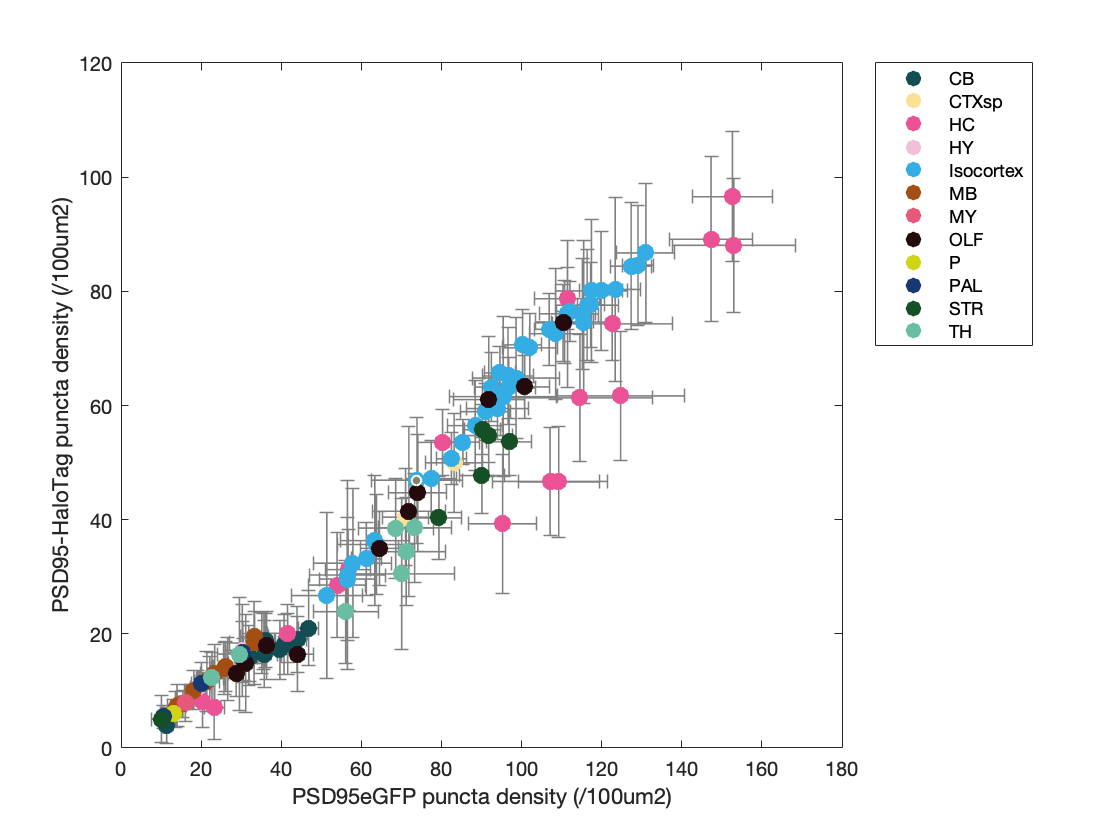


hold off
saveas(gcf,'correlation_density_Halo_vs_eGFP_ALLsubregions_bycolour','png')
saveas(gcf,'correlation_density_Halo_vs_eGFP_ALLsubregions_bycolour','pdf')